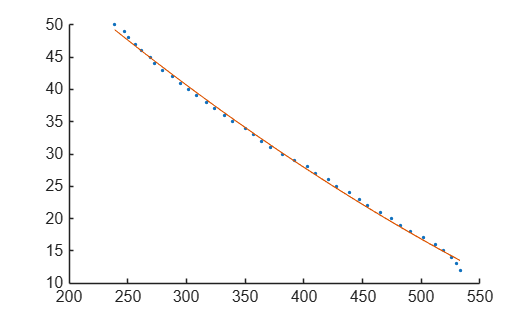

distance = linspace(1, 50, 50); % in cm
output = [173, 212, 264, 283, 294, 313, 336, 353, 396, 470, 516, 533, 530, 526, 519, 512, 502, 491, 482, 475, 465, 454, 447, 439, 428, 421, 410, 403, 392, 382, 372, 364, 357, 350, 339, 332, 324, 317, 309, 302, 295, 288, 280, 273, 269, 262, 257, 251, 247, 239]; % raw output

capped_distance = distance(12:end);
capped_output = output(12:end);

coeffs = polyfit(capped_output, capped_distance, 2);
a = coeffs(1); b = coeffs(2); c = coeffs(3);
plotted = a .* capped_output .^ 2 + b .* capped_output + c;
figure();
hold on;
plot(capped_output, capped_distance, ".")
plot(capped_output, plotted)